CameraCalibration;


			Standard Errors of Estimated Camera Parameters
			----------------------------------------------

Intrinsics
----------
Focal length (pixels):   [ 1333.7707 +/- 2.9103     1332.8945 +/- 2.8864  ]
Principal point (pixels):[  767.0637 +/- 1.2716      591.1662 +/- 1.1437  ]
Radial distortion:       [    0.0703 +/- 0.0037       -0.1904 +/- 0.0077  ]

Extrinsics
----------
Rotation vectors:
                         [    0.0608 +/- 0.0034        0.0335 +/- 0.0033        1.5415 +/- 0.0003  ]
                         [   -0.1415 +/- 0.0031       -0.3623 +/- 0.0030       -0.7940 +/- 0.0004  ]
                         [   -0.3486 +/- 0.0015        0.3479 +/- 0.0015       -0.0041 +/- 0.0004  ]
                         [    0.0191 +/- 0.0017        0.5804 +/- 0.0018        0.0162 +/- 0.0004  ]
                         [   -0.2515 +/- 0.0050       -0.2794 +/- 0.0052        1.5264 +/- 0.0009  ]
                         [   -0.4045 +/- 0.0021        0.4554 +/- 0.0021        1.5155 +/- 0.0005  ]
 

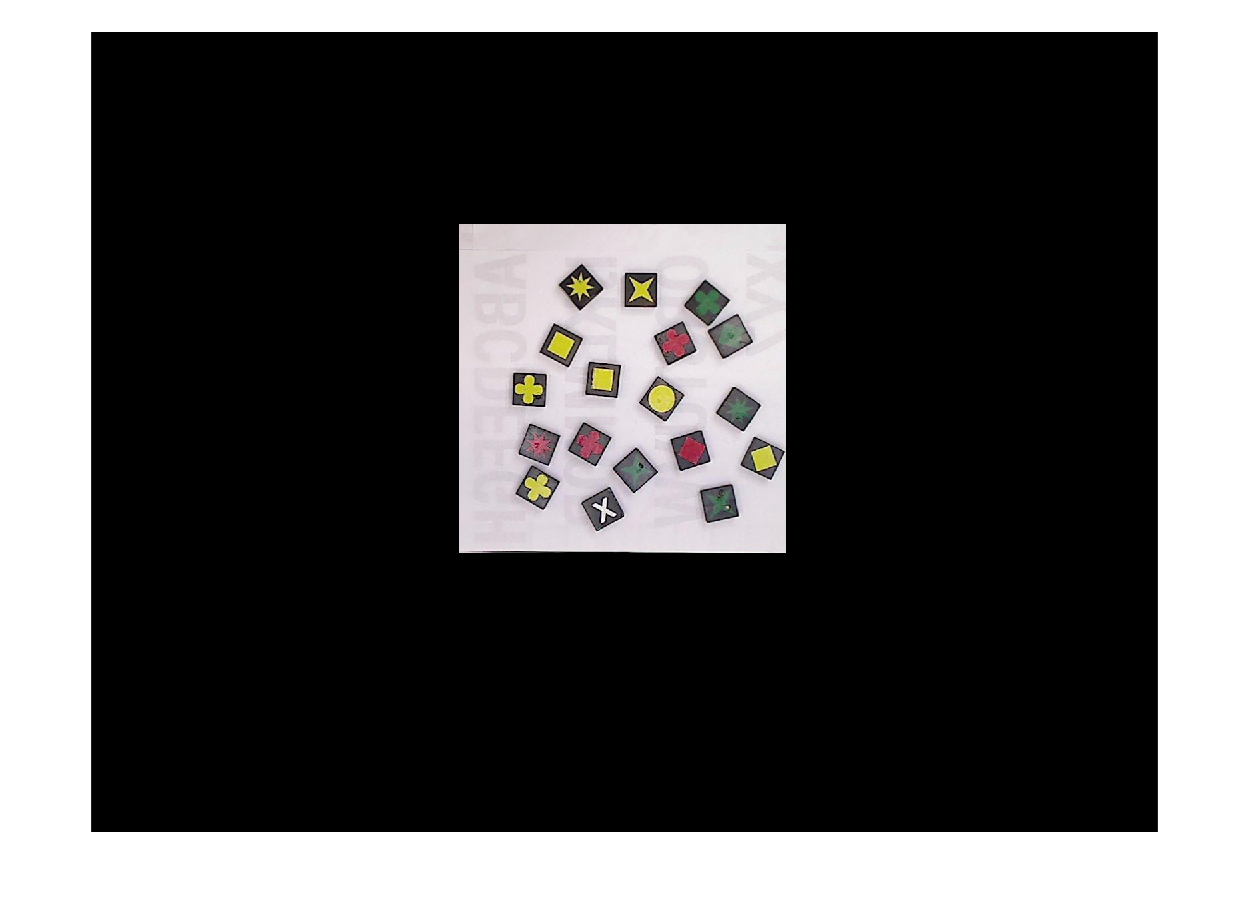

%% Identify shapes and colour of the pattern
table_Img = imread(['Proper_Pics\Patterns\Pattern22.jpg']);
table_Img = undistortImage(table_Img, cameraParams);
table_Img = segmentSection(table_Img, 552, 1043, 288, 782);
figure; imshow(table_Img);

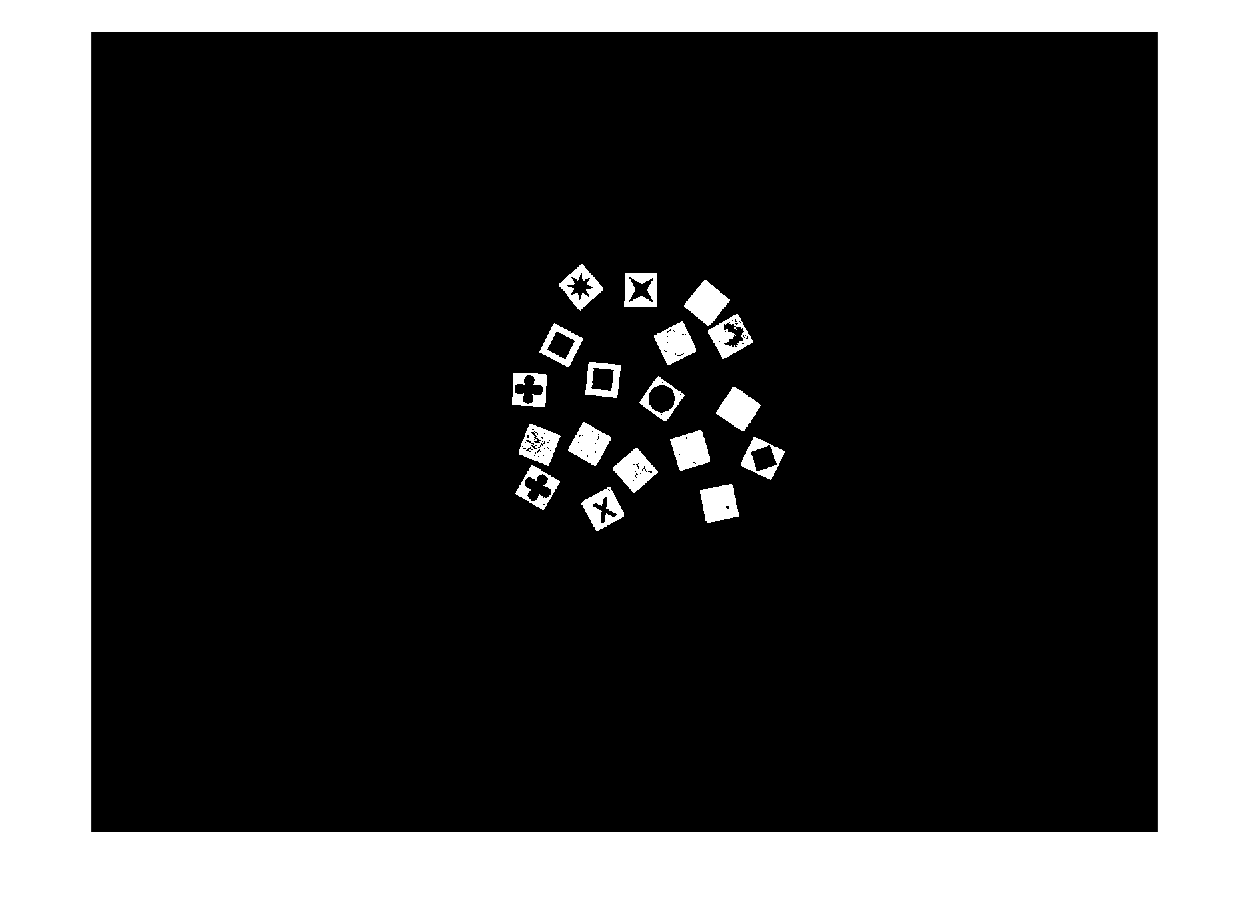


table_ImgBW = ~im2bw(table_Img);
table_ImgBW = segmentSection(table_ImgBW, 552, 1043, 288, 782);
table_ImgBW = removeLettersAndNumbers(table_ImgBW);
table_ImgBW = bwareaopen(table_ImgBW,100);
figure; imshow(table_ImgBW);

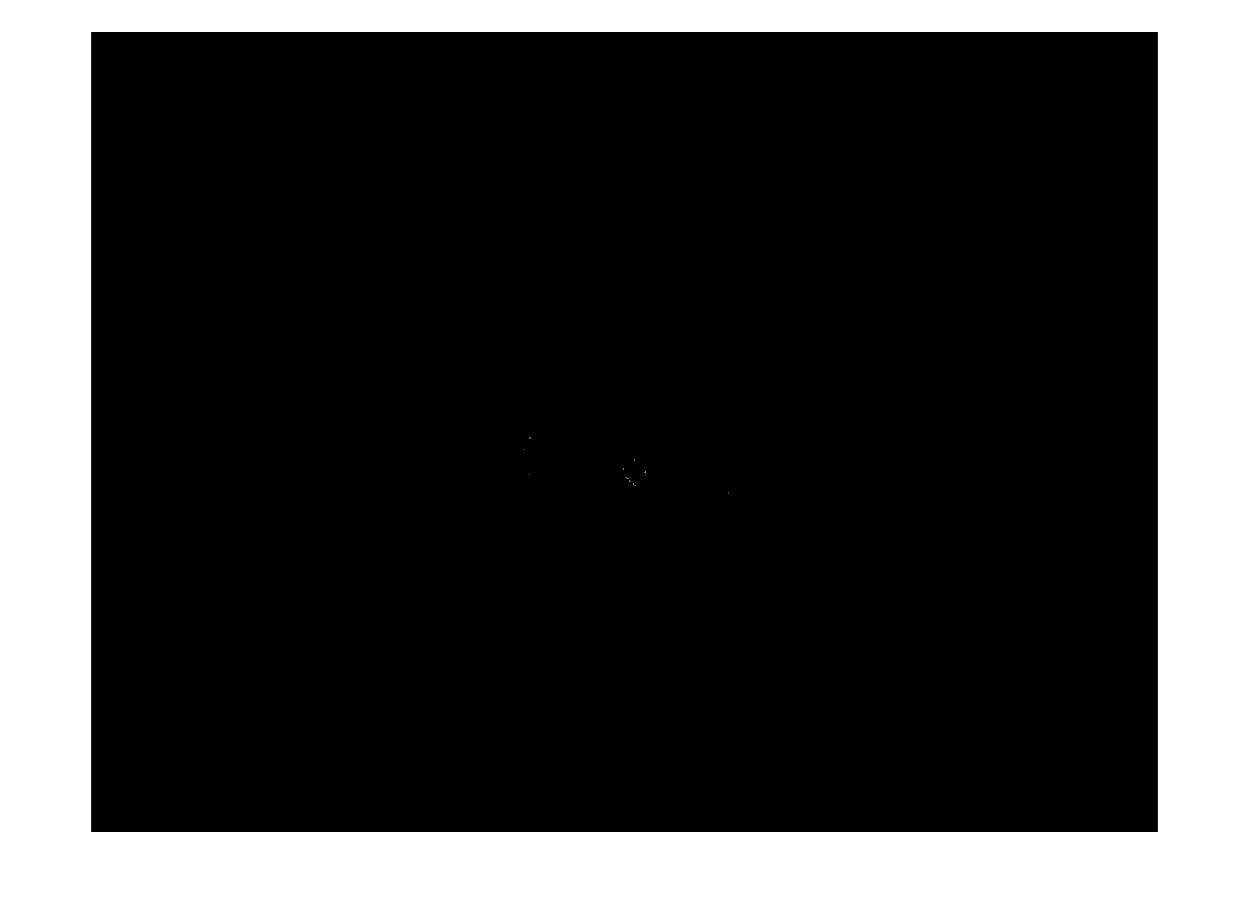


table_Img = imsharpen(table_Img, 'Radius', 5, 'Amount', 1.5);
[myPatternBlueBW,myPatternBlue] = createPatternBlueMask3(table_Img);
myPatternBlueBW = bwareaopen(myPatternBlueBW,200);
figure; imshow(myPatternBlue);

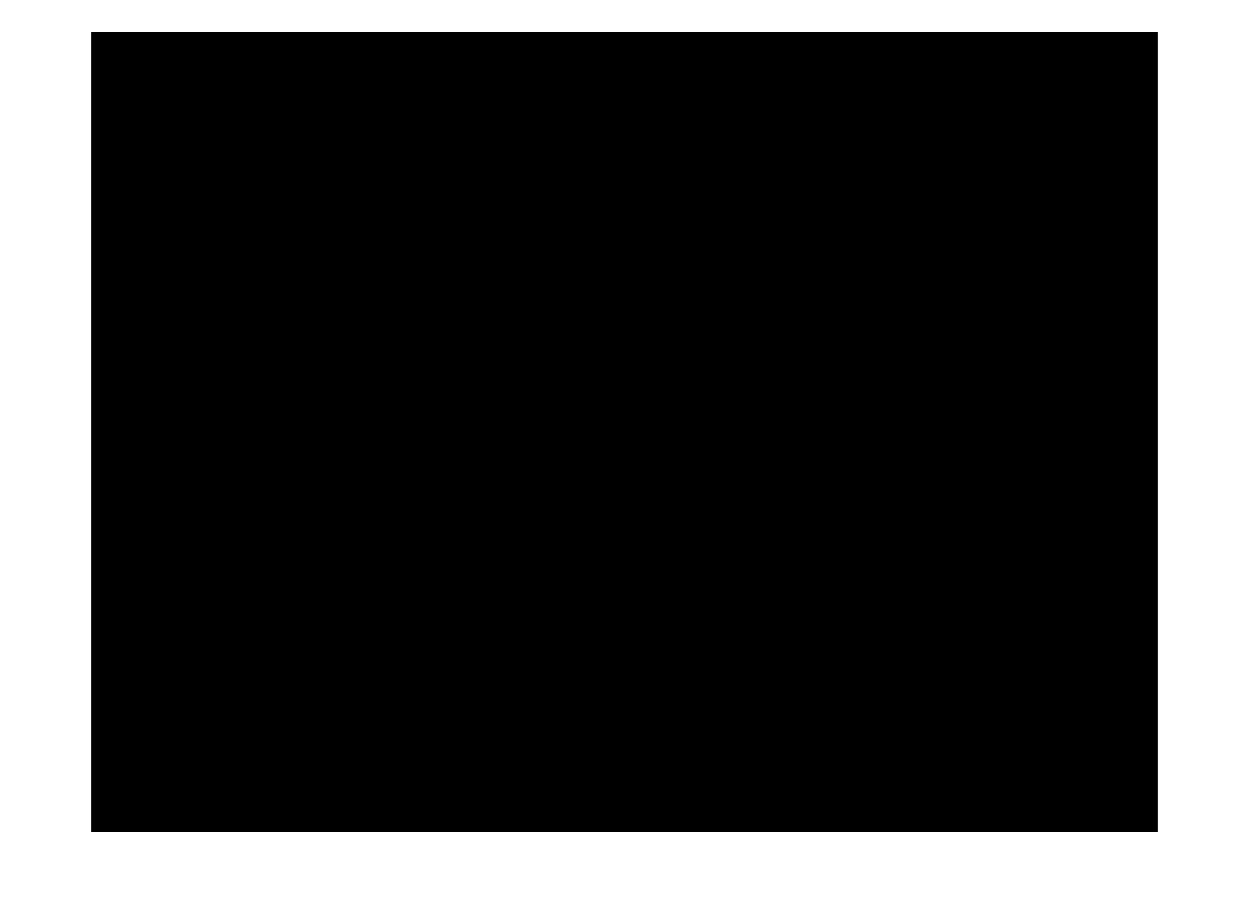

figure; imshow(myPatternBlueBW);


[blueShape, blueCentroid, blueOrientation] = identifyAllBlueShapes(myPatternBlueBW, table_ImgBW);


%{
s = regionprops(myPatternGreenBW, 'Centroid');
centroids = vertcat(s.Centroid);
n = 2;
blockBW = removeOtherShapes(table_ImgBW, centroids(n,:));
shapeBW = removeOtherShapes(myPatternGreenBW, centroids(n,:));
shapeBW = rotateToOriginal(shapeBW, blockBW);
figure; imshow(shapeBW);

seSquare = strel('Square', 25);
shapeBW2 = imopen(shapeBW, seSquare);
figure; imshow(shapeBW2);

length(find(shapeBW2))
%}